clear
load data3.mat
n=length(data.CzasLokalnyUTC0100);
T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);
Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;
TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;
X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

locs=compressorCycles(X(1,:));
x = FeatureExtract(X(4,:),locs);
f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);


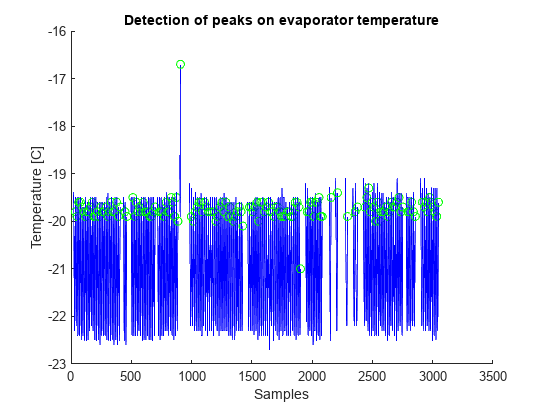

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
hold on
TF = isoutlier(fridge_air_temp_p2p);

for i=2:length(x)
    
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X(4,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X(4,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

load GABoundedTestingResults.mat

% % for i = 1:length(usableDataIndex)
% for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y{i},params{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
%         t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}));
% end

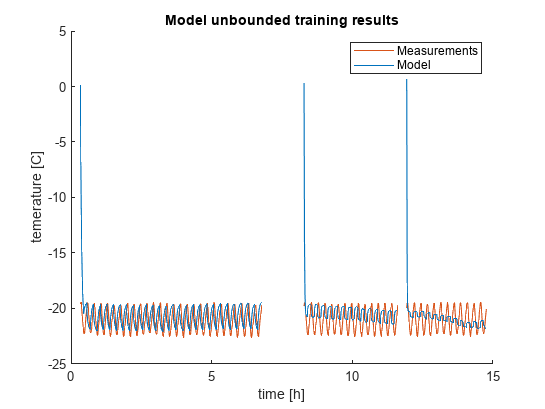

figure
hold on
% for i = 1:length(usableDataIndex)
for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

Multiple runs show great variability in performance and repeatability

% for i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y1{i},params1{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
%         t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}));
% end

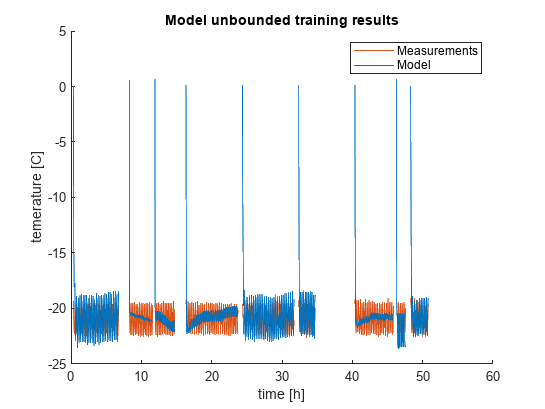

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y1{i},'Color','#0072BD')
end
hold off
title('Model unbounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

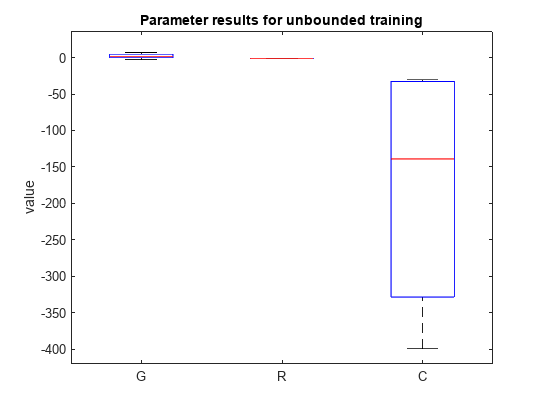

for i = 1:length(params1)
resu1(i,:)=params1{i};
end
figure
boxplot(resu1,'Labels',{'G','R','C'})
ylabel('value')
title('Parameter results for unbounded training')

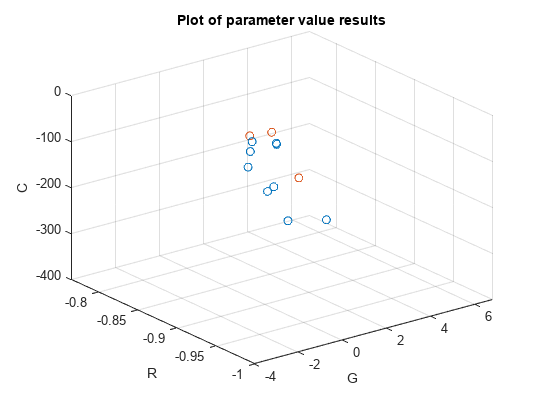

figure
plot3(resu1(:,1),resu1(:,2),resu1(:,3),'o');hold on

for i = 1:length(params)
resu(i,:)=params{i};
end
plot3(resu(:,1),resu(:,2),resu(:,3),'o');
grid on
xlabel('G')
ylabel('R')
zlabel('C')
title('Plot of parameter value results')

% % for i = 1:length(usableDataIndex)
% for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y2{i},params2{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
%         t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}),...
%         [0.001 1 1]);
% end

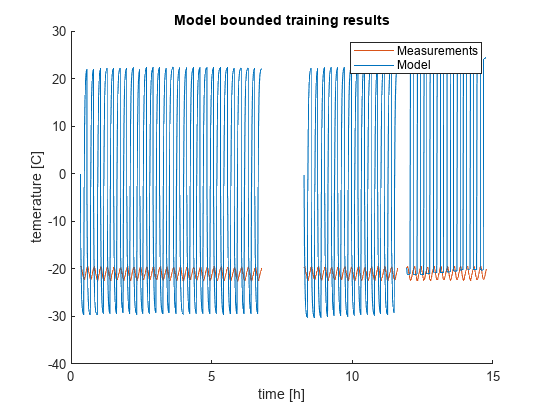

figure
hold on
% for i = 1:length(usableDataIndex)
for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y2{i},'Color','#0072BD')
end
hold off
title('Model bounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

% for i = 1:length(usableDataIndex)
% % for i = 1:3
%     t_sim=T*(0:length(usableDataIndex{i})-1);
%     [y3{i},params3{i}]=GATrain(X(1,usableDataIndex{i}), X(3,usableDataIndex{i}),...
%         t_sim, X(4,usableDataIndex{i}(1)), X(4,usableDataIndex{i}),...
%         [0.001 1 1]);
% end

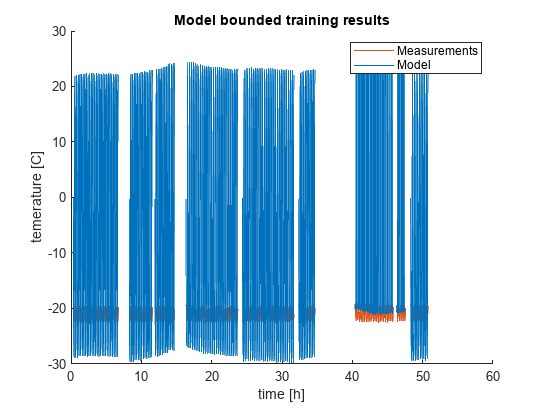

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i})/(60*60),X(4,usableDataIndex{i}),'Color','#D95319')
    plot(t(usableDataIndex{i})/(60*60),y3{i},'Color','#0072BD')
end
hold off
title('Model bounded training results')
xlabel('time [h]')
ylabel('temerature [C]')
legend('Measurements','Model')

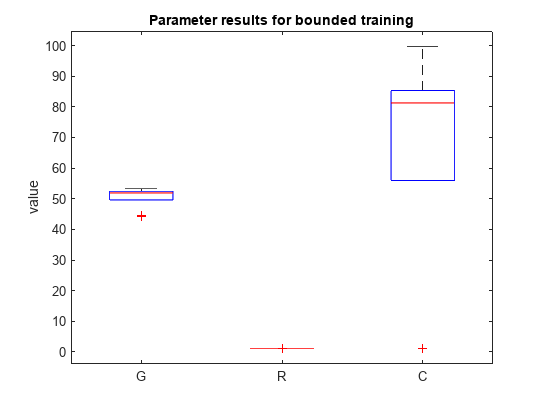

for i = 1:length(params3)
resu2(i,:)=params3{i};
end
figure
boxplot(resu2,'Labels',{'G','R','C'})
ylabel('value')
title('Parameter results for bounded training')

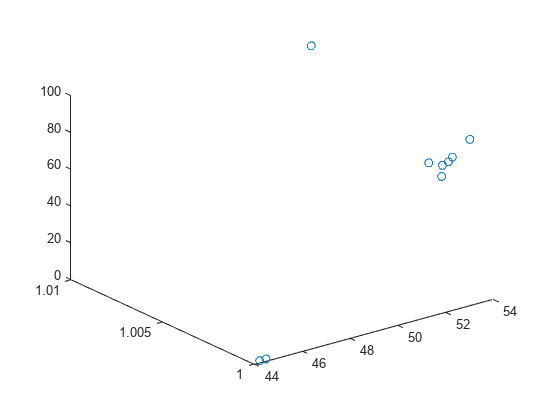

figure
plot3(resu2(:,1),resu2(:,2),resu2(:,3),'o');